# Taller 10:

1.a

f = @(t,y) t;
a=0;b=1;
h= 1/4;
M=4;
ya=1;
% Euler
E1 = euler (f, a, b, ya, M)

E1 =          0    1.0000
    0.2500    1.0000
    0.5000    1.0625
    0.7500    1.1875
    1.0000    1.3750


syms t
syms y
F = t

$$F = t$$

df = deriveFn (F, 4)

df = function_handle with value:
    @(t,y)[t,1.0,0.0,0.0]


df = function_handle with value:
    @(t,y)[t,1.0,0.0,0.0]


% Taylor de orden 2.
 df

df = function_handle with value:
    @(t,y)[t,1.0,0.0,0.0]


 T2 = taylor (df, a, b, ya, M)

T2 =          0    1.0000
    0.2500    1.0313
    0.5000    1.1250
    0.7500    1.2813
    1.0000    1.5000


***CON ESTA RUTINA NO ES NECESARIO CALCULAR LAS DERIVADAS***

 T = taylorN(F,4, a, b, ya, M)

T =          0    1.0000
    0.2500    1.0313
    0.5000    1.1250
    0.7500    1.2813
    1.0000    1.5000


b.

f = @(t,y) 5*t^4*y;
a=0;b=1;
h= 1/4;
M=4;
ya=1;
% Euler
E1 = euler (f, a, b, ya, M)

E1 =          0    1.0000
    0.2500    1.0000
    0.5000    1.0049
    0.7500    1.0834
    1.0000    1.5119


% Taylor de orden 4:
syms t
syms y
F = 5*t^4*y

$$F = 5\,t^{4}\,y$$

df = deriveFn (F, 4)

df = function_handle with value:
    @(t,y)[t.^4.*y.*5.0,t.^3.*y.*(t.^5.*5.0+4.0).*5.0,t.^2.*y.*(t.^5.*6.0e+1+t.^10.*2.5e+1+1.2e+1).*5.0,t.*y.*(t.^5.*4.8e+2+t.^10.*6.0e+2+t.^15.*1.25e+2+2.4e+1).*5.0]


df = function_handle with value:
    @(t,y)[t.^4.*y.*5.0,t.^3.*y.*(t.^5.*5.0+4.0).*5.0,t.^2.*y.*(t.^5.*6.0e+1+t.^10.*2.5e+1+1.2e+1).*5.0,t.*y.*(t.^5.*4.8e+2+t.^10.*6.0e+2+t.^15.*1.25e+2+2.4e+1).*5.0]


T4 = taylor (df, a, b, ya, M)

T4 =          0    1.0000
    0.2500    1.0000
    0.5000    1.0295
    0.7500    1.2566
    1.0000    2.5706


% Taylor de orden 2.
df = deriveFn (F, 2)

df = function_handle with value:
    @(t,y)[t.^4.*y.*5.0,t.^3.*y.*(t.^5.*5.0+4.0).*5.0,0.0,0.0]


 T2 = taylor (df, a, b, ya, M)

T2 =          0    1.0000
    0.2500    1.0000
    0.5000    1.0147
    0.7500    1.1763
    1.0000    2.0437


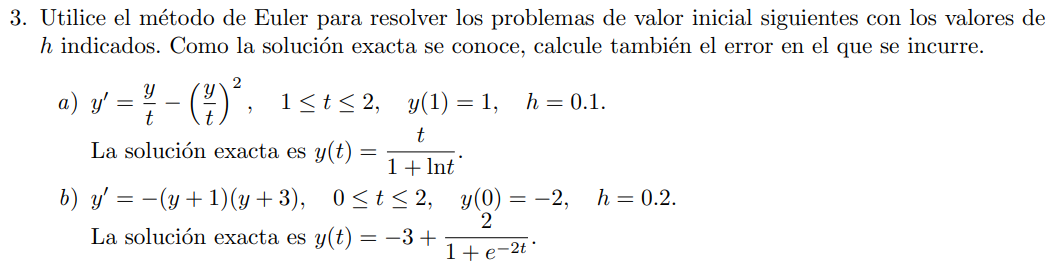

a.

f = @(t,y) y/t-(y/t)^2;
a=1; b=2; 
ya= 1 ;% condicion inicial
n = (b-a)/0.1

n = 10

h = (b-a)/n

h = 0.1000

M = 10 ;% # sub intervalos

E = euler (f, a, b, ya, M)

E =     1.0000    1.0000
    1.1000    1.0000
    1.2000    1.0083
    1.3000    1.0217
    1.4000    1.0385
    1.5000    1.0577
    1.6000    1.0785
    1.7000    1.1004
    1.8000    1.1233
    1.9000    1.1467



% La sln aproximada es     1.1707

solucion = @(t) t./(1+log(t))

solucion = function_handle with value:
    @(t)t./(1+log(t))


solucion(2)-E(end,2) % Error cometido 

ans = 0.0106

 (solucion(2)-E(end,2))/solucion(2) % Error relativo 

ans = 0.0090

Por metodo de taylor

 % Taylor de orden 4:
syms t
syms y
F = y/t-(y/t)^2

$$F = \frac{y}{t}-\frac{y^{2}}{t^{2}}$$

df = deriveFn (F, 4)

df = function_handle with value:
    @(t,y)[-1.0./t.^2.*y.^2+y./t,-1.0./t.^4.*y.^2.*(t-y.*2.0),1.0./t.^6.*y.^2.*(t.^2-y.^2.*6.0),1.0./t.^8.*y.^2.*(t.*y.^2.*6.0-t.^2.*y-t.^3+y.^3.*1.2e+1).*2.0]


df = function_handle with value:
    @(t,y)[-1.0./t.^2.*y.^2+y./t,-1.0./t.^4.*y.^2.*(t-y.*2.0),1.0./t.^6.*y.^2.*(t.^2-y.^2.*6.0),1.0./t.^8.*y.^2.*(t.*y.^2.*6.0-t.^2.*y-t.^3+y.^3.*1.2e+1).*2.0]


a=1; b=2; 
ya= 1 ;% condicion inicial
n = (b-a)/0.1

n = 10

h = (b-a)/n

h = 0.1000

M = 10 ;% # sub intervalos
T4 = taylor (df, a, b, ya, M)

T4 =     1.0000    1.0000
    1.1000    1.0043
    1.2000    1.0150
    1.3000    1.0298
    1.4000    1.0476
    1.5000    1.0673
    1.6000    1.0885
    1.7000    1.1107
    1.8000    1.1337
    1.9000    1.1573


solucion(2)-T4(end,2) % Error cometido 

ans = -2.7167e-05

(solucion(2)-T4(end,2))/solucion(2) % Error relativo 

ans = -2.2999e-05

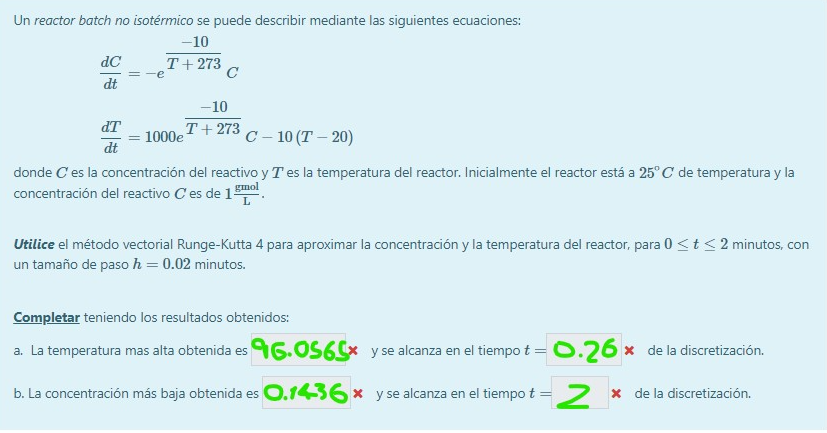

 c = @(t,c) -exp(-10/(+273))*c

c = function_handle with value:
    @(t,c)-exp(-10/(+273))*c


 
 a= 0

a = 0

 b= 2

b = 2

 n= (b-1)/0.02

n = 50

 M=50 % numero intervalos

M = 50

 ya = 1 % Condicion inicial

ya = 1

***Rugi-Kutann de orden 4 (rutinas lo llaman heun)***

Con el mismo ejemplo anterior...

H = heun (c, a, b, ya, M)

H =          0    1.0000
    0.0400    0.9622
    0.0800    0.9258
    0.1200    0.8908
    0.1600    0.8571
    0.2000    0.8246
    0.2400    0.7934
    0.2800    0.7634
    0.3200    0.7346
    0.3600    0.7068


 R = rk4 (c, a, b, ya, M)

R =          0    1.0000
    0.0400    0.9622
    0.0800    0.9258
    0.1200    0.8908
    0.1600    0.8571
    0.2000    0.8246
    0.2400    0.7934
    0.2800    0.7634
    0.3200    0.7346
    0.3600    0.7068
